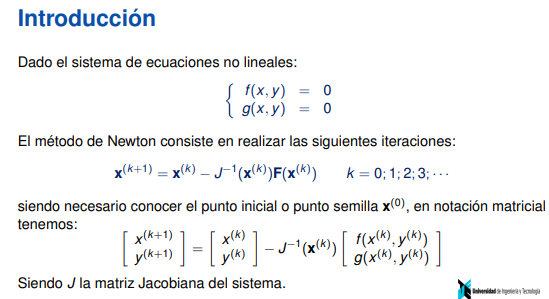

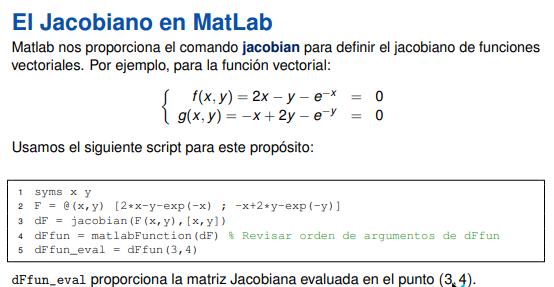

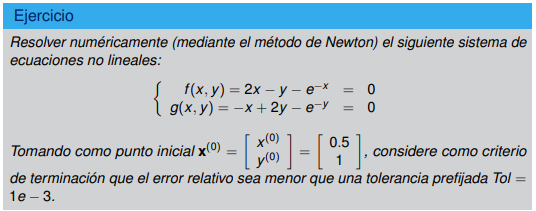


syms x y                                              % Declara x e y como variables simbólicas

F = [2*x-y-exp(-x); -x+2*y-exp(-y)];                  % Define el sistema de ecuaciones no lineales

dF = jacobian(F,[x y]);                               % Calcula simbólicamente la matriz Jacobiana

Ffun = matlabFunction(F,'Vars',{x,y});                % Convierte F en una función numérica

dFfun = matlabFunction(dF,'Vars',{x,y});              % Convierte la Jacobiana en una función numérica

x0 = [0.5; 1];                                        % Define el punto inicial o punto semilla

Tol = 1e-3;                                           % Define la tolerancia del criterio de parada

dr = Inf;                                             % Inicializa el error relativo con infinito

k = 0;                                                % Inicializa el contador de iteraciones

fprintf(' k          x              y            Error\n') % Imprime el encabezado de la tabla

 k          x              y            Error



fprintf('%2d    %12.8f   %12.8f       ---\n',k,x0(1),x0(2)) % Imprime el punto inicial

 0      0.50000000     1.00000000       ---



while dr > Tol                                        % Repite mientras el error sea mayor que la tolerancia

    Ffun_eval = Ffun(x0(1),x0(2));                    % Evalúa F en el punto actual

    dFfun_eval = dFfun(x0(1),x0(2));                  % Evalúa la matriz Jacobiana en el punto actual

    x1 = x0 - inv(dFfun_eval)*Ffun_eval;              % Aplica la fórmula de Newton para obtener el nuevo punto

    dr = norm(x1-x0,'inf')/norm(x1,'inf');            % Calcula el error relativo con norma infinito

    k = k + 1;                                        % Incrementa el contador de iteraciones

    fprintf('%2d    %12.8f   %12.8f   %12.8e\n', ... % Define el formato de impresión
        k,x1(1),x1(2),dr)                         % Imprime x, y y el error de la iteración

    x0 = x1;                                          % Actualiza el punto para la siguiente iteración

end                                                   % Finaliza el ciclo iterativo

 1      0.55879231     0.54671330   8.11189927e-01
 2      0.56711288     0.56708497   3.59217180e-02
 3      0.56714329     0.56714329   1.02824143e-04



fprintf('\nSolucion aproximada:\n')                   % Imprime el título del resultado final


Solucion aproximada:



disp(x1)                                              % Muestra la solución aproximada

    0.5671
    0.5671




fprintf('Numero de iteraciones = %d\n',k)             % Muestra el número total de iteraciones

Numero de iteraciones = 3


Ahora realizaremos Newton vectorizado:

syms x1 x2                                                % Declara las variables simbólicas x1 y x2

x = [x1; x2];                                             % Define el vector simbólico de variables

F = [2*x1-x2-exp(-x1); ...                                % Define la primera ecuación del sistema
    -x1+2*x2-exp(-x2)];                                  % Define la segunda ecuación del sistema

dF = jacobian(F,x);                                       % Calcula simbólicamente la matriz Jacobiana

Ffun = matlabFunction(F,'Vars',{x});                      % Convierte F en una función numérica vectorizada

dFfun = matlabFunction(dF,'Vars',{x});                    % Convierte la Jacobiana en una función numérica vectorizada

x0 = [0.5; 1];                                            % Define el punto inicial o punto semilla

Tol = 1e-3;                                               % Define la tolerancia del criterio de parada

dr = Inf;                                                 % Inicializa el error relativo con infinito

k = 0;                                                    % Inicializa el contador de iteraciones

fprintf(' k          x              y            Error\n') % Imprime el encabezado de la tabla

 k          x              y            Error



fprintf('%2d    %12.8f   %12.8f       ---\n', ...         % Define el formato del punto inicial
    k,x0(1),x0(2))                                    % Imprime el punto inicial

 0      0.50000000     1.00000000       ---



while dr > Tol                                            % Repite mientras el error sea mayor que la tolerancia

    Ffun_eval = Ffun(x0);                                 % Evalúa el vector F en el punto actual

    dFfun_eval = dFfun(x0);                               % Evalúa la matriz Jacobiana en el punto actual

    x1 = x0 - inv(dFfun_eval)*Ffun_eval;                  % Calcula la nueva aproximación con Newton

    dr = norm(x1-x0,'inf')/norm(x1,'inf');                % Calcula el error relativo usando norma infinito

    k = k + 1;                                            % Incrementa el contador de iteraciones

    fprintf('%2d    %12.8f   %12.8f   %12.8e\n', ...     % Define el formato de salida
        k,x1(1),x1(2),dr)                             % Imprime x, y y el error relativo

    x0 = x1;                                              % Actualiza el vector para la siguiente iteración

end                                                       % Finaliza el ciclo while

 1      0.55879231     0.54671330   8.11189927e-01
 2      0.56711288     0.56708497   3.59217180e-02
 3      0.56714329     0.56714329   1.02824143e-04



fprintf('\nSolucion aproximada:\n')                       % Imprime el título del resultado final


Solucion aproximada:



disp(x1)                                                  % Muestra el vector solución aproximado

    0.5671
    0.5671




fprintf('Numero de iteraciones = %d\n',k)                 % Muestra el número total de iteraciones

Numero de iteraciones = 3


La diferencia principal respecto al código anterior está en estas líneas: